% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

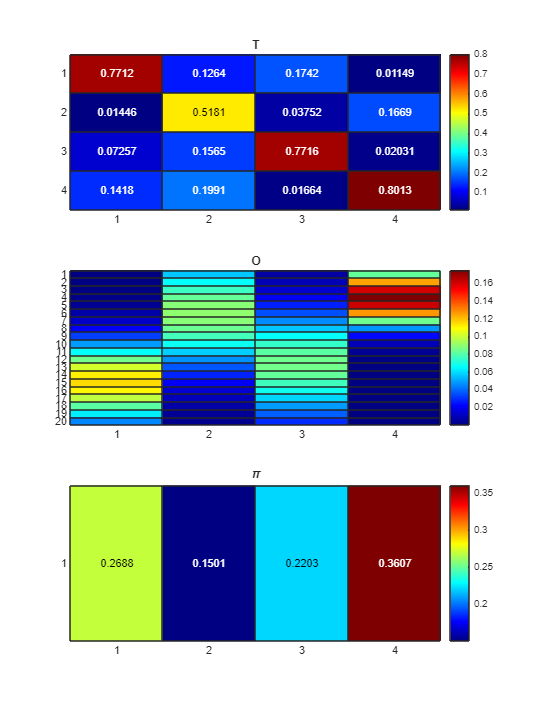

k = 4;
d = 20;

options.method = "random";
options.lambda = 5;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);

figure('Renderer', 'painters', 'Position', [10 10 900 1200])


subplot(3, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(3, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

subplot(3, 1, 3);
h = heatmap(pi, Colormap=jet());
h.Title = '\pi';

Calculate true joint probability tensor $$P_3^\infty$$

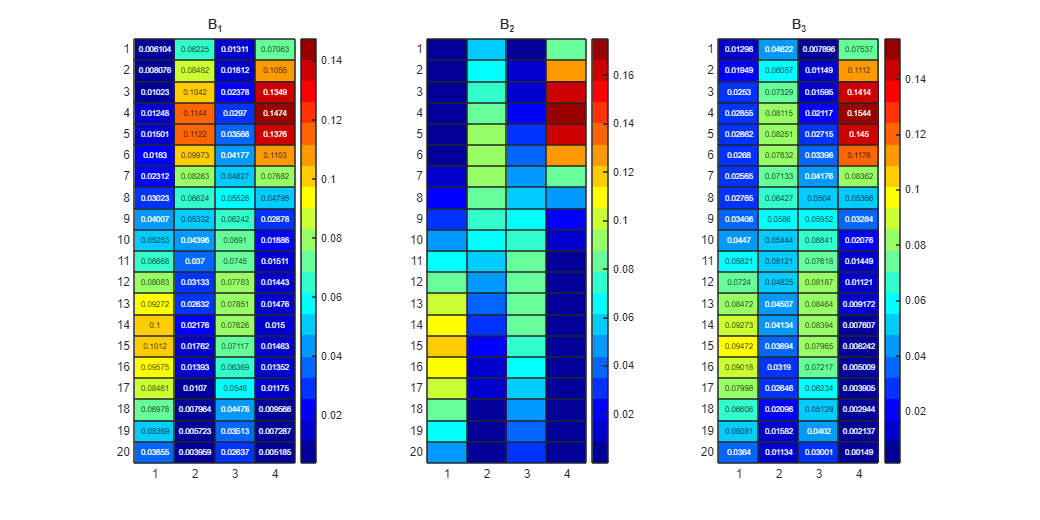


D = {};
D{1} = Stochasticize(O * diag(pi) * T' * inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);

P3_inf = cpdgen(D)/k;

PlotFactorMatrices(D);

Generate the joint probability tensor (JPT) $P_3^n$ by sampling n datasamples from the HMM matrices


T_seq = 1e6;

Taug = [0, pi; zeros(k, 1), T'];
Oaug = [zeros(1, d); O'];
[seq,states] = hmmgenerate(T_seq, Taug, Oaug);

tic
[P3_n, convergence] = estimate_joint_prob(seq, d, P3_inf);
toc

Elapsed time is 0.221006 seconds.



alpha = 1e-6;
% P3_n = laplacian_smoothing_mle(P3_n, alpha);


Plot the convergence of the sampled JPT

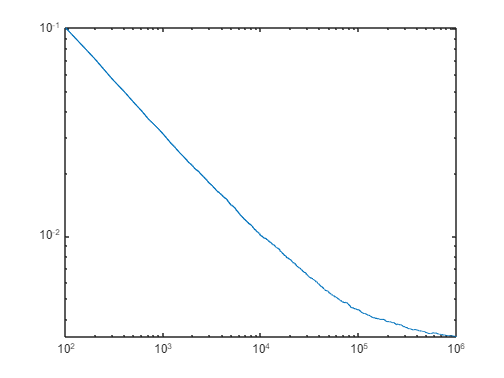

figure()
loglog(linspace(0, T_seq, length(convergence)), convergence)

Apply structured ridge regression CPD to obtain factor matrices.


lambda_T = 0.01;
lambda_O = 0.0001;
eta = 0.05;
max_iter = 1000;

tic
[B1, B2, B3, T_hat, O_hat] = cpd_als_kl(P3_n, k, lambda_T, lambda_O, max_iter, eta);
toc

Elapsed time is 0.127759 seconds.


T_hat2 = Stochasticize(pinv(Stochasticize(B2)) * Stochasticize(B3))

T_hat2 =     0.8740    0.0534    0.3042    0.0702
    0.1151    0.8616    0.0203    0.1840
    0.0066    0.0826    0.6389    0.4663
    0.0042    0.0024    0.0366    0.2796




Pbest = PermutationFit(T, T_hat);

T_hat = Pbest * T_hat * Pbest';
O_hat = O_hat * Pbest';

norm(T-T_hat, "fro") + norm(O-O_hat, "fro")

ans = 0.5458

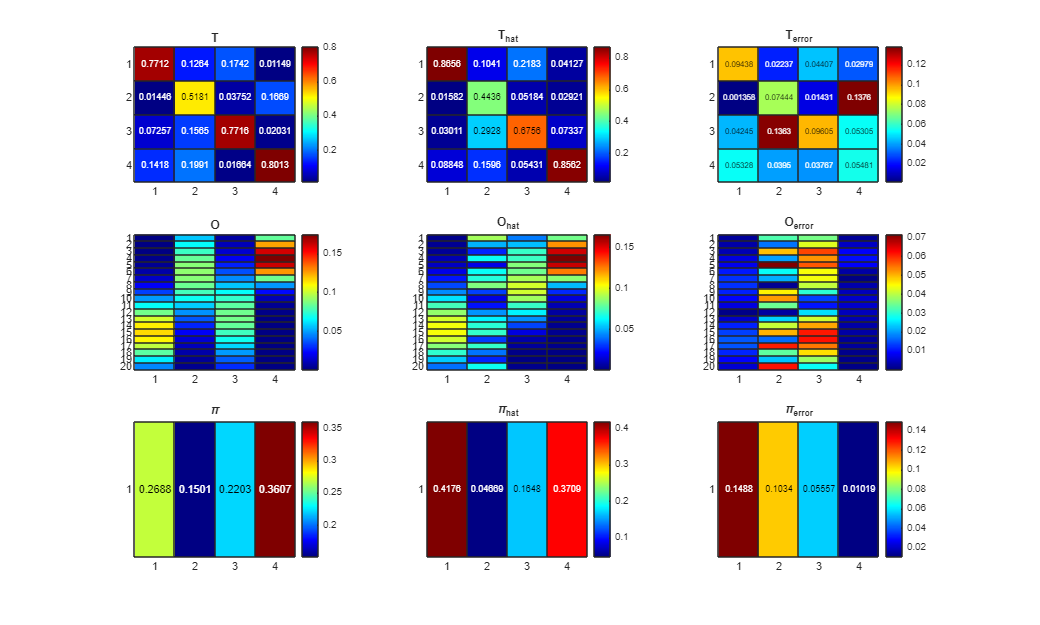


pi_hat = findStationaryDistribution(T_hat');


plotHMMError(T, T_hat, O, O_hat, pi, pi_hat);

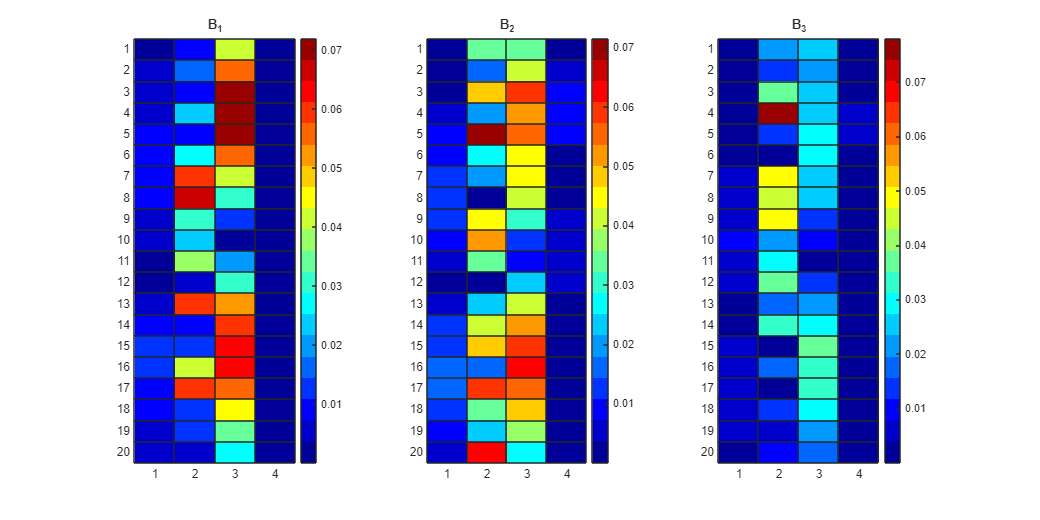

PlotFactorMatrices({abs(B1 * Pbest'-D{1}), abs(B2* Pbest'-D{2}), abs(B3* Pbest'-D{3})});